# 时变特性周期噪声的自适应反馈控制（Jafari & Ioannou, 2015）

## 理论背景

脚本是对Saeid Jafar, Petros Ioannou和Lael Rudd 2015年JVC论文的仿真复现。文章设计的控制器结构包含$F\left(s\right)$与$K\left(s,\theta \right)$两部分，非常简单。以下内容按照原文分节，通过易于理解循序渐进的仿真复现过程。

## 1 固定控制器设计

引入固定控制器$F\left(s\right)$的目的是为了在$\omega \in \left\lbrack 0,{\bar{\;\omega \;} }_{\max } \right\rbrack$上尽可能展平$W\left(s\right)=F\left(s\right)G_{0\;} \left(s\right)\Lambda \;\left(s\right)$的频谱。

由于其中$\Lambda \left(s\right)$的各对角元素均为直流增益1，且带宽$>{\bar{\;\omega \;} }_{\max }$的低通滤波器，只需要合理地选取$F\left(s\right)$使得$G_0^{\prime } \left(s\right)$在带宽内具有足够带的增益即可。

作者给出的构造过程如下：

- 先取$\tilde{G_0 } \left(s\right)=G_{0\;} \left(s\right)$；

- 假如$\tilde{G_0 } \left(s\right)$有虚轴零点，则将其平移至LHP$s=-\delta_0 \pm j\omega_0$，其中$\delta_0$是一个小的正实数；

- 假如$\tilde{G_0 } \left(s\right)$有不稳定零点$s=\sigma_0 \pm j\omega_0$，则将其反射至LHP$s=-\sigma_0 \pm j\omega_0$.

- 最后，取$F\left(s\right)=\kappa_0 \frac{\alpha^m }{{\left(s+\alpha \right)}^m }\tilde{\;G_0^{-1} } \left(s\right)$

% 定义示例中的G0(s)
s = tf('s');
G0 = (s*(s^2 + 4)*(s - 0.8)*(s + 1.4)) / ...
     ((s + 0.5)^3 * (s + 2)^2 * (s + 3))


G0 =
 
           s^5 + 0.6 s^4 + 2.88 s^3 + 2.4 s^2 - 4.48 s
  --------------------------------------------------------------
  s^6 + 8.5 s^5 + 27.25 s^4 + 41.38 s^3 + 30.88 s^2 + 11 s + 1.5
 
连续时间传递函数。


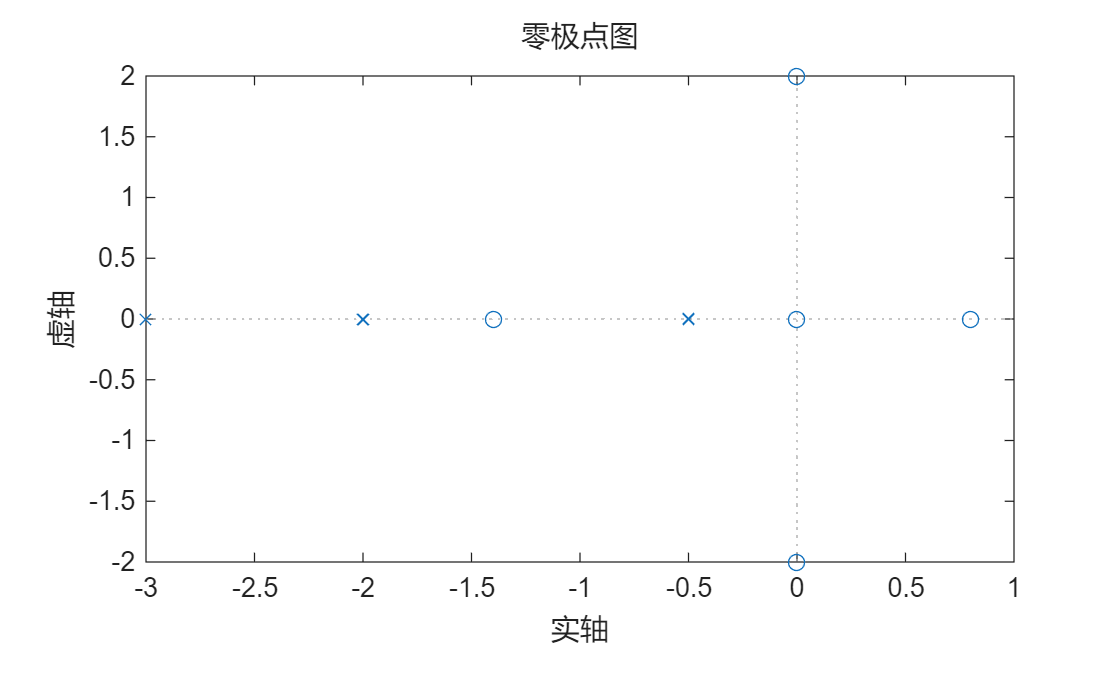

pzmap(G0); grid on;

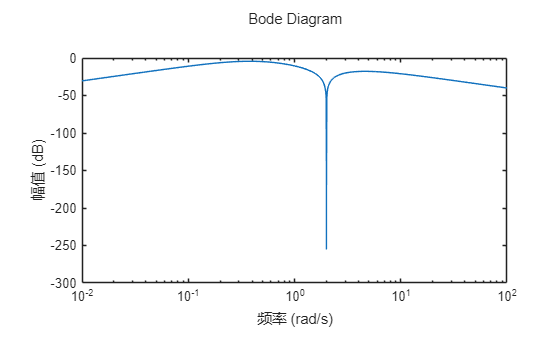

bodemag(G0); grid on;

% 设计滤波器F(s)
F = designLTIFilter(G0, 1, 0.01, 300, 2, 300)

=== LTI滤波器F(s)设计过程 ===
原始G0零点:    0.0000 + 0.0000i  -0.0000 - 2.0000i  -0.0000 + 2.0000i  -1.4000 + 0.0000i   0.8000 + 0.0000i

原始G0极点:   -3.0000 + 0.0000i  -2.0000 + 0.0000i  -2.0000 + 0.0000i  -0.5000 - 0.0000i  -0.5000 + 0.0000i  -0.5000 + 0.0000i

原始G0增益: 1.0000

检测到虚轴零点，进行处理...
零点 +0.0000+0.0000i 移动到 -0.0100+0.0000i
零点 -0.0000+2.0000i 移动到 -0.0100+2.0000i
零点 -0.0000-2.0000i 移动到 -0.0100-2.0000i

检测到不稳定零点，进行反射...
零点 +0.8000+0.0000i 反射到 -0.8000+0.0000i

修改后的G̃0(s):   zpk - 属性:

                Z: {[5×1 double]}
                P: {[6×1 double]}
                K: 1
    DisplayFormat: 'roots'
         Variable: 's'
          IODelay: 0
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               

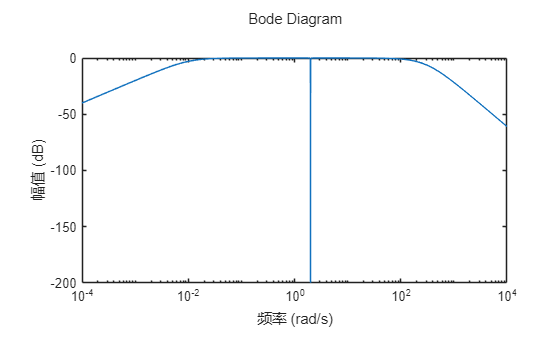

bodemag(F*G0); grid on;

## 2 自适应控制器设计

文中的自适应滤波器设计为：$K\left(s,\theta \;\left(t\right)\right)=\sum_{k=0}^{N-1} \theta_k \left(t\right)\frac{\lambda^{N-k} }{{\left(s+\lambda \right)}^{N-k} }$。这一滤波器组由多个低通滤波器并联而成，每一级低通滤波器增益参数作为自适应参数。为便于理解参数对自适应参数的作用，提供绘图分析：

举例而言，若取$N=5$，$\lambda =500$，滤波器组如下：

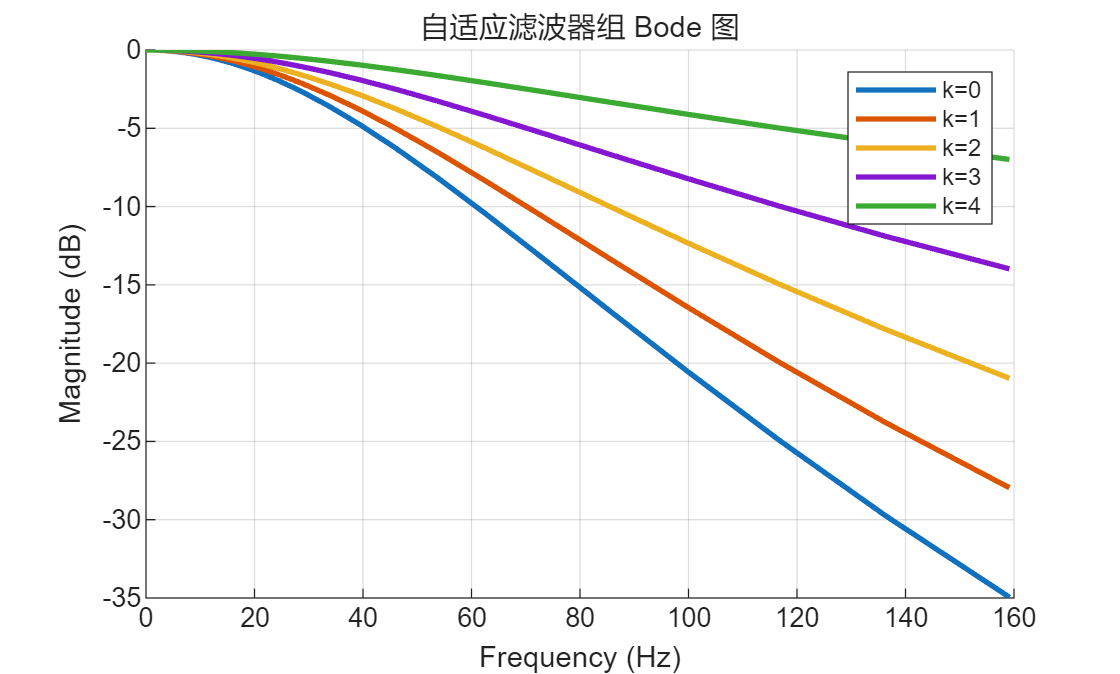

% 自适应滤波器组Bode图绘制示例
N = 5;
lambda = 500;
s = tf('s');
Ts = 1/10000; % 可选采样周期，若需离散化可用c2d

figure; hold on;
colors = lines(N);
for k = 1:N
    num = lambda^(N-k+1);
    den = (s + lambda)^(N-k+1);
    Hk = num / den;
    [mag, phase, w] = bode(Hk, {1e-3, 1e3});
    mag = squeeze(mag);
    phase = squeeze(phase);
    semilogx(w/(2*pi), 20*log10(mag), 'Color', colors(k,:), 'LineWidth', 2, ...
        'DisplayName', sprintf('k=%d', k-1));
end
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('自适应滤波器组 Bode 图');
legend show; grid on;

为实现滤波器权重系数的自适应，设计如下的观测与参数自适应环节：

对$\hat{z} =\theta {\;}^{\top \;} \phi$选用最小二乘算法


$$\dot{P} \left(t\right)=-P\frac{\phi \phi^{\top \;} }{1+\gamma_0 \phi^{\top \;} \phi \;}P$$



$$\varepsilon =\frac{\left(z-\hat{z} \right)}{1+\gamma_0 \phi^{\top \;} \phi \;}$$



$$\dot{\theta \;} \left(t\right)=\textrm{Proj}\left(P\varepsilon \phi \right)=\left\lbrace \begin{array}{ll}
P\varepsilon \phi  & \theta \in {\mathbb{S}}_0 \;\textrm{or}\;\theta \in \delta \mathbb{S}\;\textrm{and}\;{\left(P\varepsilon \phi \right)}^{\top \;} \nabla g\le 0\\
P\varepsilon \phi -P\frac{\nabla g\nabla g^{\top \;} }{\nabla g^{\top \;} P\nabla g}P\varepsilon \phi  & \textrm{otherwise}
\end{array}\right.$$


其中，${\mathbb{S}}_0 =\left\lbrace \theta \in {\mathbb{R}}^N |g\left(\theta \right)=\theta^{\top \;} \theta -\theta_{\max }^2 <0\right\rbrace$而$\delta \mathbb{S}=\left\lbrace \theta \in {\mathbb{R}}^N |g\left(\theta \right)=\theta^{\top \;} \theta -\theta_{\max }^2 =0\right\rbrace$，分别表示$\mathbb{S}$的内部和边界。

## 3 完整的数值仿真实验

### （1）问题设置

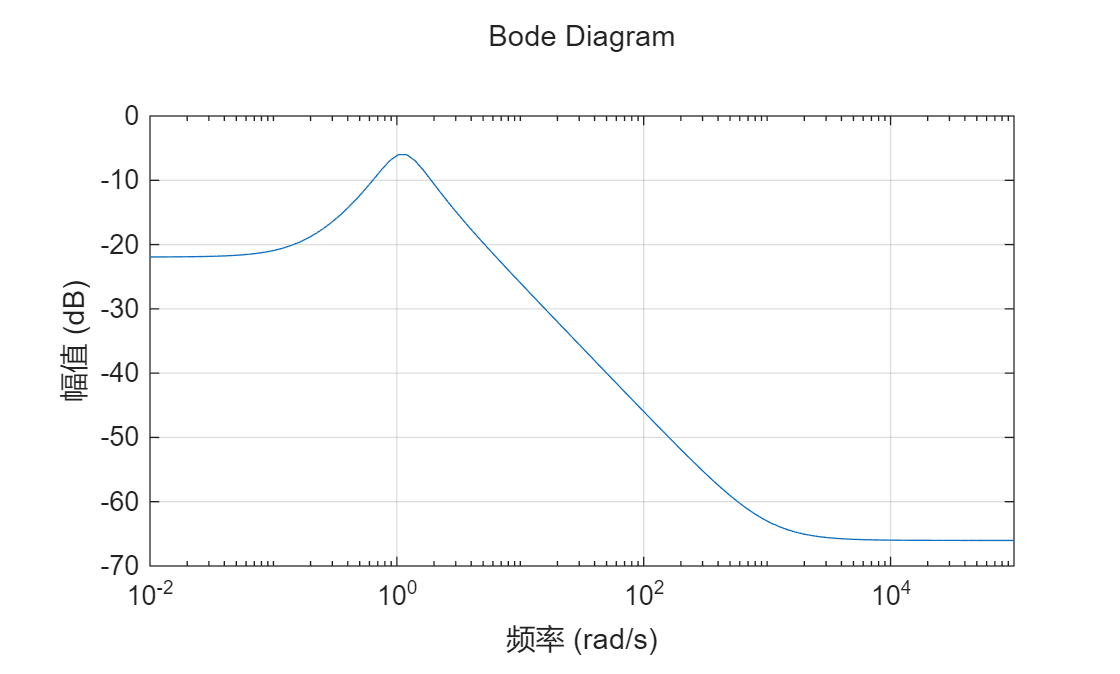

clear; close all; clc;
%% 参数设置
fs = 10000;              % 采样频率 [Hz]
Ts = 1/fs;              % 采样周期
Tsim = 5;               % 仿真总时间 [s]
Nsim = Tsim*fs;         % 仿真步数
t = (0:Nsim-1)*Ts;

%% 1. 定义名义模型 G0 和不确定性
s = tf('s');
G0 = 0.5*(s-0.2)/(s^2+s+1.25);           % 名义模型
epsi = 0.001;           % 不确定性幅度
Delta = epsi*s;
G = minreal(G0*(1+Delta)); % 实际模型

%% 2. 扰动信号 d(t)
% 固定频率分量
A = [0.6 0.7];          % 幅值
f = [70 187];           % Hz
phi = [0 pi/3];         % 相位
d = zeros(1,Nsim);
for k=1:length(A)
    d = d + A(k)*sin(2*pi*f(k)*t + phi(k));
end
% 加入小随机噪声
d = d + 0.02*randn(1,Nsim);

bodemag(G); grid on;

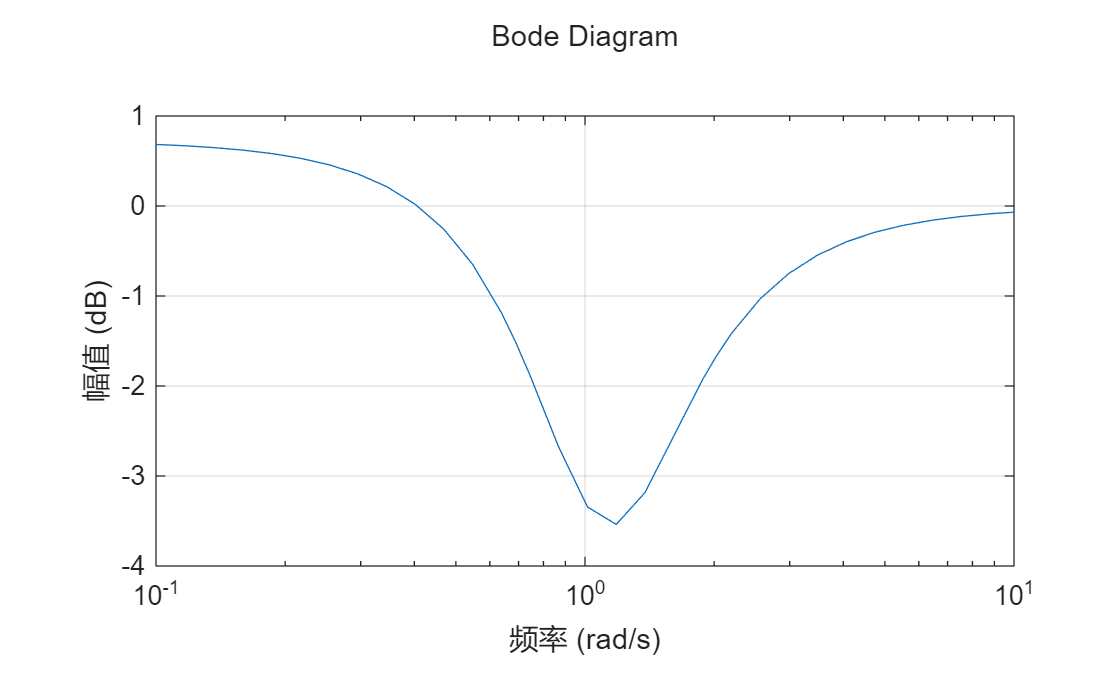

bodemag(1/(1+G)); grid on;

### （1）固定控制器设计

%% 3. 控制器结构 (F(s)+K(s,theta))
% 固定滤波器 F(s)
k0 = 0.5;
delta0 = 0.; 
alpha = 500; 
m = 2;
omega_max = 600;
F = designLTIFilter(G0, k0, delta0, alpha, m, omega_max)

=== LTI滤波器F(s)设计过程 ===
原始G0零点:     0.2000

原始G0极点:   -0.5000 - 1.0000i  -0.5000 + 1.0000i

原始G0增益: 0.5000

检测到不稳定零点，进行反射...
零点 +0.2000+0.0000i 反射到 -0.2000+0.0000i

修改后的G̃0(s):   zpk - 属性:

                Z: {[-0.2000]}
                P: {[2×1 double]}
                K: 0.5000
    DisplayFormat: 'roots'
         Variable: 's'
          IODelay: 0
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]

使用指定的相对度 m = 2

设计完成！
F(s) = k0 * (α^m/(s+α)^m) * G̃0^(-1)(s)
其中: k0=0.50, α=500.00, m=2

F =
 
  2.5e05 (s^2 + s + 1.25)
  -----------------------
     (s+500)^2 (s+0.2)
 
连续时间零点/极点/增益模型。


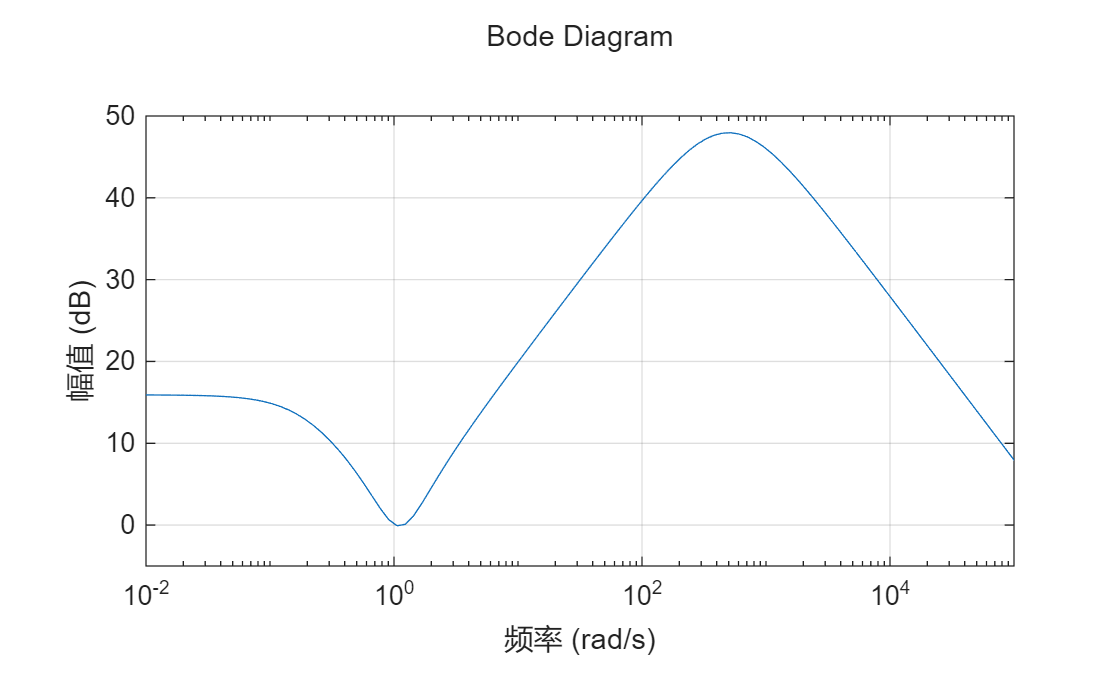

% 离散化 F(s)
Fd = c2d(F, Ts, 'tustin');
[numF, denF] = tfdata(Fd, 'v');
stateF = zeros(max(length(denF), length(numF))-1, 1);
bodemag(F); grid on;

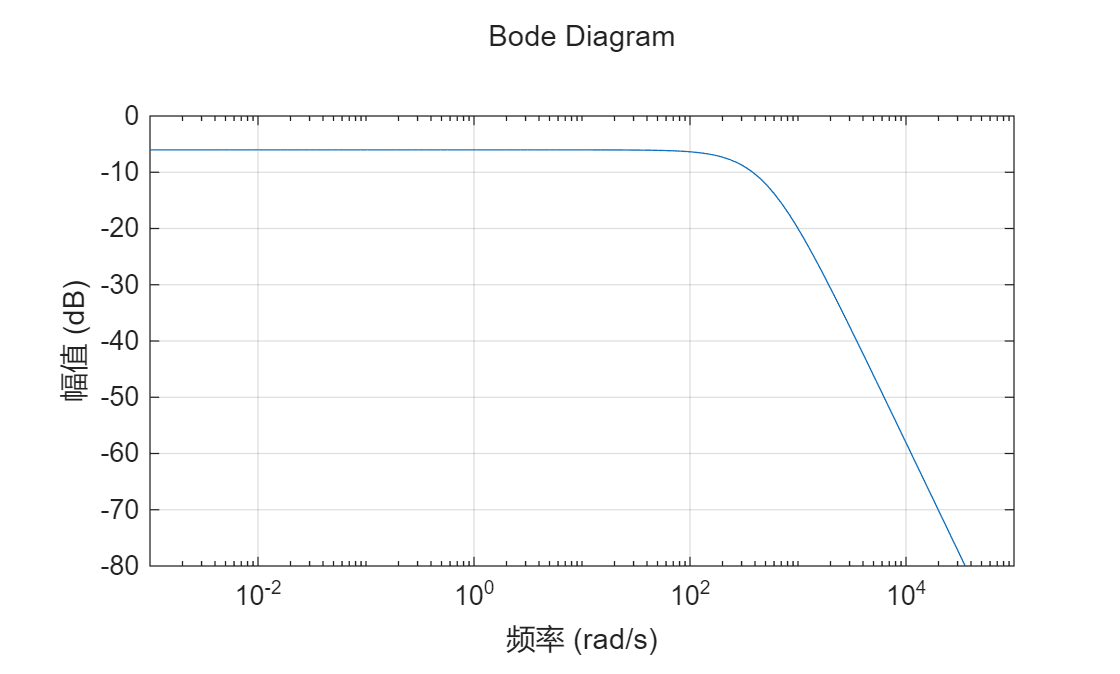

bodemag(F*G0); grid on;

### （2）自适应控制器设计

% K(s,theta) 参数化（简化成 FIR 滤波器）
Nparam = 20;            % 参数个数 N >= 2*nf
theta = zeros(Nparam,1);
phi_reg = zeros(Nparam,1);

%% 4. 自适应律参数
P = eye(Nparam)*100;    % 初始协方差
lambda = 0.99;          % 遗忘因子

%% 5. 仿真循环
for k = Nparam+1:Nsim
    % F(s) 对扰动 d 的滤波
    [uF_k, stateF] = filter(numF, denF, d(k), stateF);

    % 自适应部分
    phi_reg = -y(k-1:-1:k-Nparam).';
    u(k) = uF_k + theta.'*phi_reg;

    % 系统响应
    y(k) = lsim(c2d(G, Ts), u(k), [0 Ts]); 
    y(k) = y(k) + d(k);

    % 自适应律更新 (RLS)
    eps_k = y(k);
    K_gain = P*phi_reg/(lambda + phi_reg.'*P*phi_reg);
    theta = theta - K_gain*eps_k;
    P = (P - K_gain*phi_reg.'*P)/lambda;
end

%% 6. 绘图结果
figure;
plot(t,y); xlabel('Time [s]'); ylabel('Output y(t)');
title('ANC with Adaptive Feedback');

## 5 附录

function F = designLTIFilter(G0, k0, delta0, alpha, m, omega_max)
% 设计LTI滤波器F(s)用于展平W(s) = F(s)G0(s)的频谱
%
% 输入参数:
%   G0       - 名义植物模型传递函数
%   k0       - 增益参数 (默认: 1)
%   delta0   - 设计常数（默认：0.01）
%   alpha    - 设计常数 (默认: 0.1)
%   m        - 相对度整数 (默认: 自动计算)
%   omega_max- 最大频率 (默认: 100 rad/s)
%
% 输出:
%   F        - 设计的LTI滤波器传递函数
%
% 设计步骤基于论文中的算法:
% 1. G̃0(s) = G0(s)
% 2. 如果G̃0(s)在虚轴上有零点，将其移动到左半平面
% 3. 如果G̃0(s)有不稳定零点，通过虚轴反射使其稳定
% 4. F(s) = k0 * (α^m/(s+α)^m) * G̃0^(-1)(s)

if nargin < 2, k0 = 1; end
if nargin < 3, delta0 = 0.01; end
if nargin < 4, alpha = 0.1; end
if nargin < 5, m = []; end
if nargin < 6, omega_max = 100; end

fprintf('=== LTI滤波器F(s)设计过程 ===\n');

% 获取G0的零极点
[z, p, k] = zpkdata(G0, 'v');
fprintf('原始G0零点: '); disp(z');
fprintf('原始G0极点: '); disp(p');
fprintf('原始G0增益: %.4f\n', k);

%% 步骤1: G̃0(s) = G0(s)
G_tilde = G0;
z_modified = z;

%% 步骤2: 处理虚轴上的零点
jw_zeros = abs(real(z)) < 1e-10; % 检测虚轴零点

if any(jw_zeros)
    fprintf('\n检测到虚轴零点，进行处理...\n');
    index = find(jw_zeros)';
    for i = index
        % 复数零点: s = ±jω0 → s = -δ0 ± jω0
        z_modified(i) = -delta0 + 1j*imag(z(i));
        fprintf('零点 %+.4f%+.4fi 移动到 %+.4f%+.4fi\n', ...
            real(z(i)), imag(z(i)), real(z_modified(i)), imag(z_modified(i)));
    end
end

%% 步骤3: 处理不稳定零点（右半平面零点）
rhp_zeros = real(z_modified) > 1e-10;

if any(rhp_zeros)
    fprintf('\n检测到不稳定零点，进行反射...\n');
    for i = find(rhp_zeros)
        z_old = z_modified(i);
        z_modified(i) = -real(z_modified(i)) + 1j*imag(z_modified(i));
        fprintf('零点 %+.4f%+.4fi 反射到 %+.4f%+.4fi\n', ...
            real(z_old), imag(z_old), real(z_modified(i)), imag(z_modified(i)));
    end
end

% 构造修改后的G̃0(s)
G_tilde = zpk(z_modified, p, k);
fprintf('\n修改后的G̃0(s): '); 
disp(G_tilde);

%% 步骤4: 计算相对度m (如果未指定)
if isempty(m)
    num_zeros = length(z_modified);
    num_poles = length(p);
    m = max(1, num_poles - num_zeros + 1); % 确保m > G̃0的相对度
    fprintf('自动计算的相对度 m = %d\n', m);
else
    fprintf('使用指定的相对度 m = %d\n', m);
end

%% 步骤5: 构造F(s)
s = tf('s');

% 低通滤波器部分: α^m/(s+α)^m
LPF = (alpha^m) / (s + alpha)^m;

% G̃0的逆: 1/G̃0(s)
G_tilde_inv = 1 / G_tilde;

% 完整的F(s)
F = k0 * LPF * G_tilde_inv;

% 化简传递函数
F = minreal(F);

fprintf('\n设计完成！\n');
fprintf('F(s) = k0 * (α^m/(s+α)^m) * G̃0^(-1)(s)\n');
fprintf('其中: k0=%.2f, α=%.2f, m=%d\n', k0, alpha, m);

end